# OCS Project

## Basic scenario

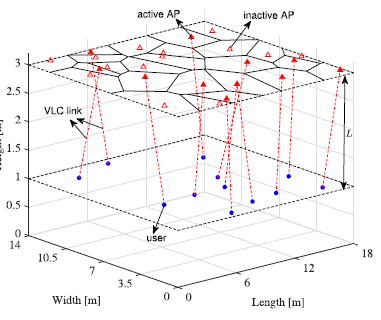

## Declaring all the relevant constants. 

- number_of_ap= Total number of AP's and Total numer of Users in the indoor environment at equidistant locations. 

- semi_angle= Semi-angle of LED = $\psi_{\frac{1}{2}}$

- fieldofView=Field of View of LED (kept at 90 deg)

- nc=reflective index of optical concentrator=  $\frac{\mathrm{Speed}\text{ }\mathrm{of}\text{ }\mathrm{light}\text{ }\mathrm{in}\text{ }\mathrm{vaccum}}{\mathrm{Phase}\text{ }\mathrm{velocity}\text{ }\mathrm{in}\text{ }\mathrm{optical}\text{ }\mathrm{material}}$  (For VLC, typical values of $\eta_c$ reside between 1 and 2 

- Apd= Area of the photodiode.

- L= Vertical height between AP and the users.

- eta= Average responsivity of a photodiode. Generally =0.58 A/W.  

clc;
clear all;
number_of_ap = 100;
accessPoints = randi([1,20],1,number_of_ap);
userPoints = randi([10,20],1,number_of_ap);
semi_angle = 45;
fieldOfView = (pi/180)*90; % changing 60 from 30
nc = 1.83;
nf = 1.33;
Apd = 1e-4;
L = 10;
eta = 0.4; % responsivity
lambdaU = 7e-7;
speedOfLight = 3e8;
beta = 3.5;
lambdaA = 0.1;

## Calculation of the total SINR.

- Ptx= Signal power

- x0= Nearest AP to the origin

- m=Order of the lambertian radiation profile. =  

-  

- thetar=angle of incidence of the link

- sigma sq= noise variance.

- lambdau=user node density

- lambdaa=ap's node density. 

- thetat=angle of irradiance

- Gain= 

- TotalGain=

cosTheta = [];
for i = 1:100
    temp = L/sqrt(L*L + accessPoints(i)*accessPoints(i));
    cosTheta = [cosTheta temp];
end
angleToRadian = [];
m = -1/log2(cos(semi_angle));
thetar = [];
for i=1:100
    thetar = [thetar acos(cosTheta(i))]; %acoc=inverse of costheta
end
alpha = [];
for i = 1:100
    gf = gain(thetar(i),fieldOfView,nf);
    gc = gain(thetar(i),fieldOfView,nc);
    temp = gf*gc*eta*Apd*(L^(m+1))/(2*pi);
    alpha = [alpha temp];
end
totalGain = [];
for i = 1:100
    temp = alpha(i)*(accessPoints(i)*accessPoints(i) + L*L);
    temp = temp^((-m+3)/2);
    totalGain = [totalGain temp];
end
[ma,ind2] = max(totalGain);
phidash = [];
for i=1:number_of_ap
    temp = (userPoints(i)-accessPoints(i))*(userPoints(i)-accessPoints(i));
    phidash = [phidash temp];
end
ind = 1.07:0.01:1.9;
sz = size(ind);
ptx = 3;
denom = 0;
sinr = [];
for j = 1:sz(2)
    for i = 1:number_of_ap
        if(i ~= ind2)
            denom = denom + (phidash(i)*phidash(i) + L*L)^(-ind(j)-3);
        end
    end
    num = (phidash(ind2)*phidash(ind2) + L*L)^(-ind(j)-3);
    sinr = [sinr num];
end
sinrdb = [];
for i = 1:sz(2)
    sinrdb = [sinrdb -10*log10(sinr(i))];
end

## Plotting the Idle probability

- $p_{\mathrm{idle}}$ is given by :  

- $\beta$=3.5= shape parameter obtained through curve fitting

- $\lambda_u$=user node density

- $\lambda_a$=Ap's node density

- **Expectation**: As the ratio of $\lambda_u$ $/$ $\lambda_a$ inceases (comes closer to 1) the overall $p_{\mathrm{idle}}$ should decrease.

- **Expectation**: For an underloaded network, e.g., λu/λa = 0.1, the AP idle probability can be as large as 0.9.

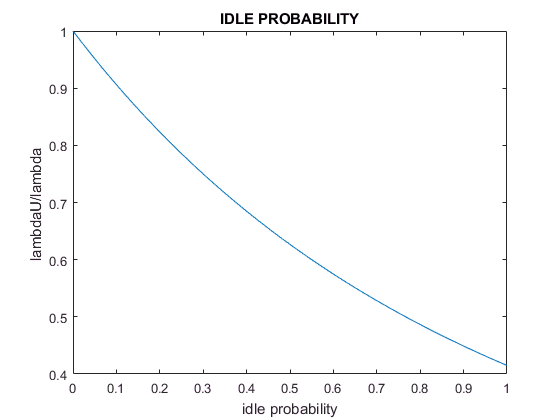

%% Calculating Idle probability
lambdaU = 0:0.001:0.1;
prob = [];
sz = size(lambdaU);
for i=1:sz(2)
    temp = (beta/(beta+lambdaU(i)/lambdaA));
    prob = [prob temp^beta];
end
temp = lambdaU/lambdaA;
plot(temp,prob);
title('IDLE PROBABILITY')
xlabel('idle probability')
ylabel('lambdaU/lambda ')

lambdahat=(1-prob)*lambdaA;

As expected idle probability is decreasing when the user density is increasing. 

## Coverage probability analysis in the low SINR regime

**A**. Asymptotic analysis of coverage probability in low SINR regime.:

- Assumption: The multiuser VLC network under consideration is interference-limited so that the SINR can be well approximated by the SIR.

- With this Assumption, we first study the distribution of the interference-to-signal ratio (ISR) at the typical user, given by ISR = ${\mathrm{SINR}}^{-1}$. The Laplace transform of the ISR is given in the following theorem.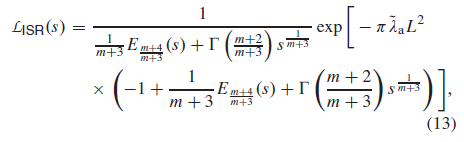

- **Expectation 1**:The denominator of the Laplace transform of the ISR is a strictly increasing function with respect to s.

- The denominator of laplace transform is plotted for two different values of semi-angle (45 and 60).

- **Expectation 2**:  The pole of Laplace transform of ISR changes as the Lambertian order of the AP changes.

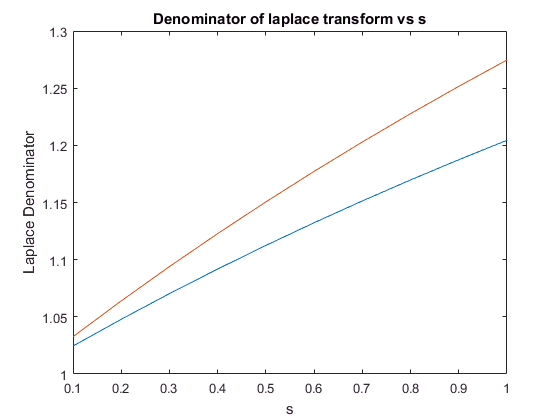

m = [-1*(1/log2(cos(pi/4))),-1*(1/log2(cos(pi/3)))];
%m=[-2.173,-1.847];

for j = 1:2
    denomi = [];
    val=0;
    for s = 0.1:0.1:1
   
        temp = ((m(j)+4)/(m(j)+3));
        gam = gamma((m(j)+2)/(m(j)+3));
        val3 = (m(j)+2)/(m(j)+3);
        integ = @(x) exp(-s*x).*x.^(-temp);
        val = ((1/(m(j)+3))*(integral(integ,1,Inf))) + ((gam)*(s.^(1/(m(j)+3))));
        denomi = [denomi val];
    end
    s = 0.1:0.1:1;
    plot(s,denomi);
    xlabel('s')
    title('Denominator of laplace transform vs s')
    ylabel('Laplace Denominator')
    hold on;
   
end 
hold off;

**B**. Outage probability in the low SINR region

- The numerical value of the pole of L(ISR) is found to be [-2.173,-1.847,-1.658]

- 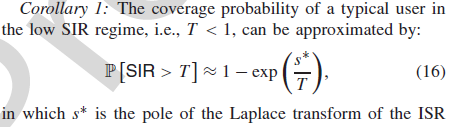

- **Remark**: The pole of the Laplace transform of the ISR does not depend on the parameter L, and therefore the coverage probability of the typical user does not depend on L.

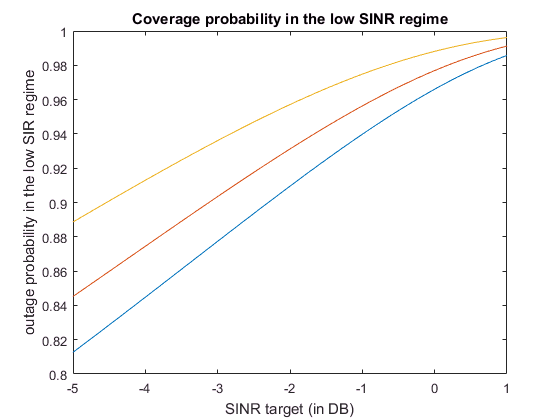

arr = [-1.658,-1.847,-2.173];
for k = 1:3
    temp = [];
    for sinr = -5:0.1:1
        temp = [temp (sinr)];
    end
    sinr = -5:0.1:1;
    sizeS = size(sinr);
    T = 0.99:-0.01:0.01;
    T = T(1:sizeS(2));
    p = 1 - (exp(arr(k)./T));
    plot(sinr,p);
    title('Coverage probability in the low SINR regime')
    %annotation('textarrow',[0.5039 0.4727],[0.3183 0.481],'String','')
    hold on;
    xlabel("SINR target (in DB)")
    ylabel('outage probability in the low SIR regime');
end
hold off;

##  Coverage probability in the interference limited case for high SINR regime

When L-->0, the coverage probability in the interference-limited scenario follows a power-law decay profile:

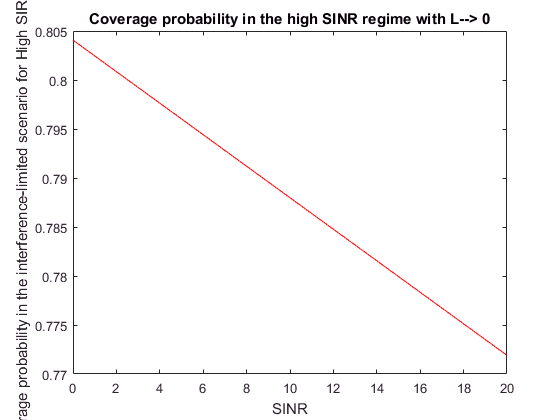

%%  coverage probability in the interference-limited scenario

t = 5:-0.01:1.01;
m = -2.173;
gamAns = gamma((m+2)/(m+3));
gamAns2 = gamma((m+4)/(m+3));
p = (gamAns.*gamAns2);
s = 0:20;
sizeSi = size(s);

t = t(1:sizeSi(2));
%prob=1/(gamAns*gamAns2))
plot(s,-t./(p),'r');
xlabel('SINR');
title("Coverage probability in the high SINR regime with L--> 0")
ylabel('coverage probability in the interference-limited scenario for High SIR regime');

%remark- this curve follows a power-law decay profile

## Upper bound on the coverage probability for the high SINR regime



%% Upper bound 
m = -2.173;
T = 0.99:-0.01:0.01;
tempM = 1/(m+3);
temp = T.^(-1/tempM);
temp2 = exp(-pi*0.5*10*0.1*0.1*10.*(T.^(tempM) - 1));
p = temp.*temp2;
%plot(T,p);


## Gaussian curve fitting for the probability mass function of $\phi_{a}^{\sim }$

**Assumption**: $\lambda_u$ =[0.03, 0.1, 0.3]

-  ag,bg and cg are constants obtained from gaussain curve fitting related to $\lambda_u$ and $\lambda_a$

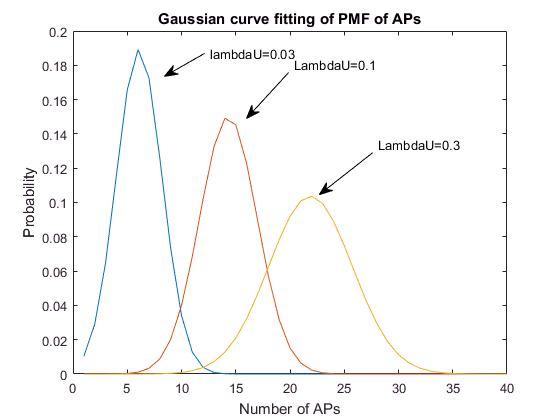

ag = [0.1894, 0.1502, 0.1037];
bg = [6.093, 14.32, 21.89];
cg = [2.985, 3.751, 5.446];

for lam=1:3
    prob = [];
    val=0;
    n = 1:40;
    for i = 1:40
        if totalGain(i) > 0
            val = val+1;
        else
            val = 0;
        end
        temp =(-1*(((val-bg(lam))/cg(lam))^2));
        pg = ag(lam)*exp(temp);
        prob = [prob pg];
    end
    plot(n,prob);
    hold on;
end
hold off;
title('Gaussian curve fitting of PMF of APs')
xlabel('Number of APs')
ylabel("Probability")

annotation('textarrow',[0.6655 0.57],[0.6364 0.5364],'String','LambdaU=0.3');
annotation('textarrow',[0.5154 0.4403],[0.8273 0.7182],'String','LambdaU=0.1');
annotation('textarrow',[0.3652 0.2935],[0.8727 0.8182],'String','lambdaU=0.03')